%% Orthorectification Parameters (from 4 GCPs + pairwise distances)
% Author:       Dr.-Ing. José Aliaga-Villagrán
% Affiliation:  Leichtweiß-Institute for Hydraulic Engineering and Water Resources
% Contact:      j.aliaga-villagran@tu-braunschweig.de / jose.aliaga.v@protonmail.com
% Version:      1.1
% Date:         2025-11-06
% Description:
%   Estimate a planar projective transform (homography) from a single
%   distortion-corrected image using 4 Ground Control Points (GCPs) and
%   the 6 pairwise distances between them. Produces:
%     • tform (image -> world)
%     • Rout_quad : tight box around the 4 GCPs, *same pixel count as input*
%     • Rout_full : full-extent world canvas that includes the entire image
%     • GSDx/GSDy : world-units per pixel (from the quad mapping)
%   Saves all parameters to a MAT file for batch rectification.
%
% CLICKING ORDER (IMPORTANT):
%   1) Double-click EXACTLY four GCP centers in the image in ANY order you like,
%      but remember that order (#1..#4).
%   2) When asked for distances, enter the SIX pairwise distances for the
%      same numbering (#1..#4): d12, d13, d14, d23, d24, d34 (units you choose).
%   3) For consistency, a *clockwise* order around the quad is recommended,
%      but not required. The script uses your clicked order as-is.
%
% Release Notes (v1.1):
%   • Robust correspondences: removed auto "TL/TR/BR/BL" re-ordering that could
%     mismatch corners (especially for trapezoids). The homography now uses the
%     exact as-clicked order for both image and world points.
%   • Added reprojection error check at the 4 GCPs.
%   • Kept side-by-side visual comparison and full-extent output.
%
% Requirements:
%   • One distortion-corrected calibration image (static camera)
%   • 4 visible GCPs on a plane (e.g., water surface)
%   • 6 pairwise distances between those 4 GCPs (same units)
%
% Acknowledgments:
%   Parts of this script and its documentation were developed with assistance
%   from OpenAI's ChatGPT (GPT-5) model.
% -------------------------------------------------------------------------

clc; close all; fprintf('=== Estimate Ortho Params (from distances) — v1.1 ===\n');

=== Estimate Ortho Params (from distances) — v1.1 ===


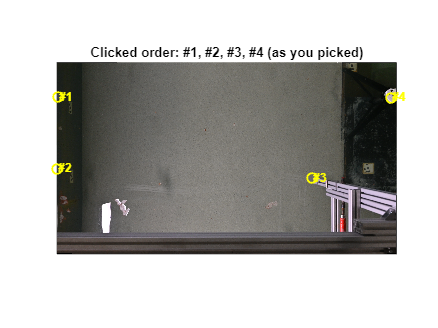


%% 1) Select ONE calibration image (already lens-distortion corrected)
[calName, calPath] = uigetfile( ...
    {'*.png;*.jpg;*.jpeg;*.tif;*.tiff','Image files'}, ...
    'Select ONE calibration image (static camera, already undistorted)');
if isequal(calName,0), error('Calibration image selection canceled.'); end
calibrationImagePath = fullfile(calPath, calName);
assert(exist(calibrationImagePath,'file')==2, 'File not found: %s', calibrationImagePath);

I = imread(calibrationImagePath);
[imgH, imgW, ~] = size(I);

%% 2) Units (label only)
ansUnits = inputdlg({'World units label (e.g., m, cm):'}, 'Units', 1, {'m'});
if isempty(ansUnits), error('Canceled.'); end
unitsLabel = strtrim(ansUnits{1}); if isempty(unitsLabel), unitsLabel = 'm'; end

%% 3) Pick EXACTLY 4 GCPs (zoom & pan; double-click to add a point)
%    TIP: Click in clockwise order around the quad if possible.
hFig = figure('Name','Zoom/Pan, then DOUBLE-CLICK 4 GCP centers (in your chosen order)','Color','w', ...
              'MenuBar','none','ToolBar','none','NumberTitle','off','WindowStyle','normal');
hAx  = axes('Parent',hFig);
hIm  = imshow(I, 'Parent', hAx, 'InitialMagnification','fit'); %#ok<NASGU>
axis(hAx,'image'); hold(hAx,'on');
title(hAx, {'Scroll = ZOOM (cursor-centered)', ...
            'Left-drag = PAN   |   Double-click = place a point', ...
            'Pick EXACTLY 4 centers in ANY order (remember it as #1..#4!).', ...
            'Press ESC to cancel.'}, 'FontWeight','bold');
impixelinfo(hFig);
grid(hAx,'on'); hAx.GridAlpha = 0.15; hAx.MinorGridAlpha = 0.10;
set(hAx,'XMinorGrid','on','YMinorGrid','on');

% Custom zoom/pan handlers
set(hFig, 'WindowScrollWheelFcn', @(~,evt) local_zoomScroll(hAx, evt, 1.2));
set(hFig, 'WindowButtonDownFcn', @(src,~) local_panStart(src, hAx));
set(hFig, 'WindowButtonUpFcn',   @(src,~) setappdata(src,'isPanning',false));

% Point picking (double-click)
pts = zeros(4,2); picked = 0;
set(hFig,'WindowButtonDownFcn', @(src,~) local_clickHandler(src,[],hAx));
setappdata(hFig,'pickedPoints',pts);
setappdata(hFig,'pickedCount',picked);

uiwait(hFig);
if ~ishandle(hFig), error('Selection canceled (figure closed).'); end
pts    = getappdata(hFig,'pickedPoints');
picked = getappdata(hFig,'pickedCount');
delete(hFig);
if picked ~= 4, error('Need EXACTLY 4 points. You picked %d.', picked); end
imagePoints = pts;  % order = as clicked (1..4)

% Quick plot of clicked order
figure('Name','Clicked points (as picked)','Color','w'); imshow(I, 'InitialMagnification','fit'); hold on;
plot(imagePoints(:,1), imagePoints(:,2), 'yo','MarkerSize',8,'LineWidth',1.5);
text(imagePoints(:,1)+5, imagePoints(:,2), compose('#%d', (1:4).'), ...
     'Color','y','FontWeight','bold');
title('Clicked order: #1, #2, #3, #4 (as you picked)'); axis image;


%% 4) Enter SIX pairwise distances for the SAME four points (clicked order)
prompt = { ...
  'd12 (between #1 and #2):', ...
  'd13 (between #1 and #3):', ...
  'd14 (between #1 and #4):', ...
  'd23 (between #2 and #3):', ...
  'd24 (between #2 and #4):', ...
  'd34 (between #3 and #4):'};
def = {'2.000','2.236','1.000','1.414','1.000','1.414'};  % placeholders
ansD = inputdlg(prompt, sprintf('Pairwise distances (%s)', unitsLabel), [1 50], def);
if isempty(ansD), error('Canceled.'); end

d = str2double(ansD(:));
if any(~isfinite(d) | d <= 0), error('All distances must be positive finite numbers.'); end

% Build symmetric 4x4 distance matrix in the clicked order (1..4)
D = zeros(4);
D(1,2)=d(1); D(2,1)=d(1);
D(1,3)=d(2); D(3,1)=d(2);
D(1,4)=d(3); D(4,1)=d(3);
D(2,3)=d(4); D(3,2)=d(4);
D(2,4)=d(5); D(4,2)=d(5);
D(3,4)=d(6); D(4,3)=d(6);

%% 5) World coords via classical MDS — KEEP ORDER (no reindexing)
X_world = local_mds_coords_from_distances(D, 2);   % 4x2, centered at origin

% Optional aesthetic orientation (rotation & shift only) — order unchanged.
% Align edge #1->#2 roughly along +X:
v12   = X_world(2,:) - X_world(1,:);
theta = -atan2(v12(2), v12(1));
R2    = [cos(theta) -sin(theta); sin(theta) cos(theta)];
X_world = (R2 * X_world.').';
X_world = X_world - min(X_world,[],1);  % shift to positive quadrant

worldPoints = X_world;       % 4x2, same order as clicked
% imagePoints already set above in same order

%% 6) Homography (image -> world) using SAME order on both sides
tform = fitgeotrans(imagePoints, worldPoints, 'projective');

% Reprojection sanity check at the 4 GCPs
[wtx, wty] = transformPointsForward(tform, imagePoints(:,1), imagePoints(:,2));
err = hypot(wtx - worldPoints(:,1), wty - worldPoints(:,2));
rmse = sqrt(mean(err.^2));
fprintf('Reprojection RMSE @ GCPs: %.4g %s\n', rmse, unitsLabel);

Reprojection RMSE @ GCPs: 3.674e-16 m



%% 7) Output views: quad & full-extent (FULL inherits same GSDx/GSDy)
% Quad box bounds (tight around 4 world points)
xmin = min(worldPoints(:,1)); xmax = max(worldPoints(:,1));
ymin = min(worldPoints(:,2)); ymax = max(worldPoints(:,2));

% Rout covering ONLY the target quad, preserving input pixel count
Rout_quad = imref2d([imgH, imgW], [xmin xmax], [ymin ymax]);

% Pixel scales (from quad mapping)
GSDx = (xmax - xmin) / imgW;   % world units per pixel in X
GSDy = (ymax - ymin) / imgH;   % world units per pixel in Y
fprintf('GSDx = %.6g %s/px | GSDy = %.6g %s/px | ratio=%.3f\n', ...
        GSDx, unitsLabel, GSDy, unitsLabel, GSDx/max(GSDy,eps));

GSDx = 0.000138551 m/px | GSDy = 0.00100817 m/px | ratio=0.137


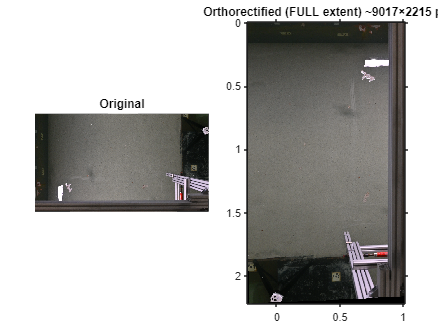


% FULL extent: map the entire image to world and bound it
imgCorners = [1 1;  imgW 1;  imgW imgH;  1 imgH];
[cx, cy]   = transformPointsForward(tform, imgCorners(:,1), imgCorners(:,2));
Xmin = min(cx); Xmax = max(cx);
Ymin = min(cy); Ymax = max(cy);

% Optional padding (in world units)
pad = 0;  % e.g., pad = 0.01;
Xmin = Xmin - pad; Xmax = Xmax + pad;
Ymin = Ymin - pad; Ymax = Ymax + pad;

% Keep same (possibly anisotropic) scales as quad for consistency
nCols_full = max(1, ceil((Xmax - Xmin) / GSDx));
nRows_full = max(1, ceil((Ymax - Ymin) / GSDy));
Rout_full  = imref2d([nRows_full, nCols_full], [Xmin, Xmax], [Ymin, Ymax]);

%% 8) Visual comparison — Original vs FULL-extent orthorectified
J_full = imwarp(I, tform, 'OutputView', Rout_full, 'FillValues', 0);

figure('Name','Visual comparison','Color','w');
tiledlayout(1,2,'Padding','compact','TileSpacing','compact');
nexttile; imshow(I, 'InitialMagnification','fit'); axis image; title('Original');
nexttile; imshow(J_full, Rout_full, 'InitialMagnification','fit'); axis image;
title(sprintf('Orthorectified (FULL extent) ~%d×%d px', size(J_full,2), size(J_full,1)));

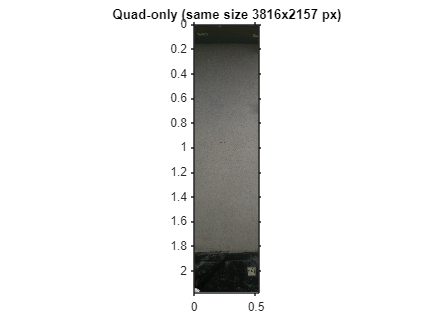


% Optional quick preview: quad-only with same pixel size as input
J_quad = imwarp(I, tform, 'OutputView', Rout_quad, 'FillValues', 0);
figure('Name','Quad-only preview (same pixel count as input)','Color','w');
imshow(J_quad, Rout_quad, 'InitialMagnification','fit'); axis image;
title(sprintf('Quad-only (same size %dx%d px)', imgW, imgH));


%% 9) Save parameters to MAT (for batch script)
defaultOut = fullfile(calPath, [erase(calName, {'.png','.jpg','.jpeg','.tif','.tiff'}) '_ortho_params.mat']);
[suggName, suggPath] = uiputfile('*.mat', 'Save orthorectification parameters as', defaultOut);
if isequal(suggName,0), error('Save canceled.'); end
outMat = fullfile(suggPath, suggName);

meta = struct();
meta.scriptVersion          = '1.1';
meta.dateUTC                = datestr(datetime('now','TimeZone','UTC'));
meta.unitsLabel             = unitsLabel;
meta.calibrationImagePath   = calibrationImagePath;
meta.imageSize              = [imgH imgW];
meta.clickedOrderNote       = 'Homography uses as-clicked order (#1..#4) for both image & world.';
meta.distanceMatrix         = D;
meta.reprojectionRMSE_units = rmse;
meta.notes                  = 'Includes Rout_quad (same size) and Rout_full (full FoV).';

save(outMat, ...
    'tform', ...
    'Rout_quad','Rout_full', ...
    'imagePoints','worldPoints', ...
    'D','GSDx','GSDy','unitsLabel','meta');

fprintf('\nSaved orthorectification parameters to:\n  %s\n', outMat);


Saved orthorectification parameters to:
  O:\_EROSVSP\05_Laborversuche\Kaiwandkolk\Hafenbecken\2025\PTV\Data_Post-Processing\Orthorectification\Frame_Cal_Marker_NZ5_undist_ortho_params.mat


fprintf('Next: use the batch script to orthorectify frames (FULL extent recommended).\n');

Next: use the batch script to orthorectify frames (FULL extent recommended).



%% ============================== Local helpers =============================
function local_zoomScroll(ax, evt, base)
    if ~ishandle(ax), return; end
    pt = get(ax,'CurrentPoint'); cx = pt(1,1); cy = pt(1,2);
    xlim0 = get(ax,'XLim'); ylim0 = get(ax,'YLim');
    if cx < xlim0(1) || cx > xlim0(2) || cy < ylim0(1) || cy > ylim0(2)
        cx = mean(xlim0); cy = mean(ylim0);
    end
    s = base^(-evt.VerticalScrollCount);
    newW = (xlim0(2)-xlim0(1))/s; newH = (ylim0(2)-ylim0(1))/s;
    dxL = (cx - xlim0(1));  dyB = (cy - ylim0(1));
    scaleL = dxL/(xlim0(2)-xlim0(1)); scaleB = dyB/(ylim0(2)-ylim0(1));
    x1 = cx - newW*scaleL;  x2 = x1 + newW;
    y1 = cy - newH*scaleB;  y2 = y1 + newH;
    set(ax,'XLim',[x1 x2],'YLim',[y1 y2]);
end

function local_panStart(fig, ax)
    if ~ishandle(ax), return; end
    if ~strcmp(get(fig,'SelectionType'),'normal'), return; end
    setappdata(fig,'isPanning',true);
    setappdata(fig,'startPoint',get(ax,'CurrentPoint'));
    setappdata(fig,'startXLim',get(ax,'XLim'));
    setappdata(fig,'startYLim',get(ax,'YLim'));
    set(fig,'WindowButtonMotionFcn',@(src,~) local_panMotion(src,ax));
end

function local_panMotion(fig, ax)
    if ~ishandle(ax) || ~getappdata(fig,'isPanning'), return; end
    cp0 = getappdata(fig,'startPoint'); cp = get(ax,'CurrentPoint');
    dx = cp(1,1) - cp0(1,1); dy = cp(1,2) - cp0(1,2);
    xl0 = getappdata(fig,'startXLim'); yl0 = getappdata(fig,'startYLim');
    set(ax,'XLim',xl0 - dx,'YLim',yl0 - dy);
end

function local_clickHandler(fig, ~, ax)
    if ~ishandle(ax), return; end
    if ~strcmp(get(fig,'SelectionType'),'open') % double-click = place point
        local_panStart(fig, ax); return;
    end
    pt = get(ax,'CurrentPoint'); pos = round(pt(1,1:2));
    if any(~isfinite(pos)), return; end
    pts = getappdata(fig,'pickedPoints'); n = getappdata(fig,'pickedCount');
    if n >= 4, return; end
    n = n + 1; pts(n,:) = pos;
    plot(ax, pos(1), pos(2), 'yo', 'MarkerSize', 8, 'LineWidth', 1.5);
    text(ax, pos(1)+5, pos(2), sprintf('#%d',n), 'Color','y','FontWeight','bold');
    setappdata(fig,'pickedPoints',pts); setappdata(fig,'pickedCount',n);
    if n == 4, uiresume(fig); end
end

function X = local_mds_coords_from_distances(D, q)
% Classical MDS (Torgerson) from distances -> q-D coordinates (centered).
    N = size(D,1);
    assert(isequal(size(D),[N N]), 'D must be square.');
    assert(all(abs(D-D.')<1e-9,'all') && all(diag(D)==0), 'D must be symmetric with zero diagonal.');
    J = eye(N) - (1/N)*ones(N);
    B = -0.5 * J * (D.^2) * J;             % double-centered Gram matrix
    [V, S] = eig((B+B')/2);                 % symmetrize for stability
    [s,ord] = sort(diag(S), 'descend'); s(s<0) = 0;
    V = V(:,ord); S = diag(s);
    X = V(:,1:q) * sqrt(S(1:q,1:q));       % centered coordinates
end
